# Fast Inverse Square Root Algorithm - Signed Fixed Point

### Alex Crownshaw

### 10/05/2024

## Fast Inv Sqrt Algorithm in C

`float` `InvSqrt (``float` `x){`

`    float xhalf = 0.5f*x;`

    `int` `i = *(``int``*)&x;`

`    i = 0x5f3759df - (i>>1);`

`    x = *(``float``*)&i;`

`    x = x*(1.5f - xhalf*x*x);`

    `return` `x;`

`}`

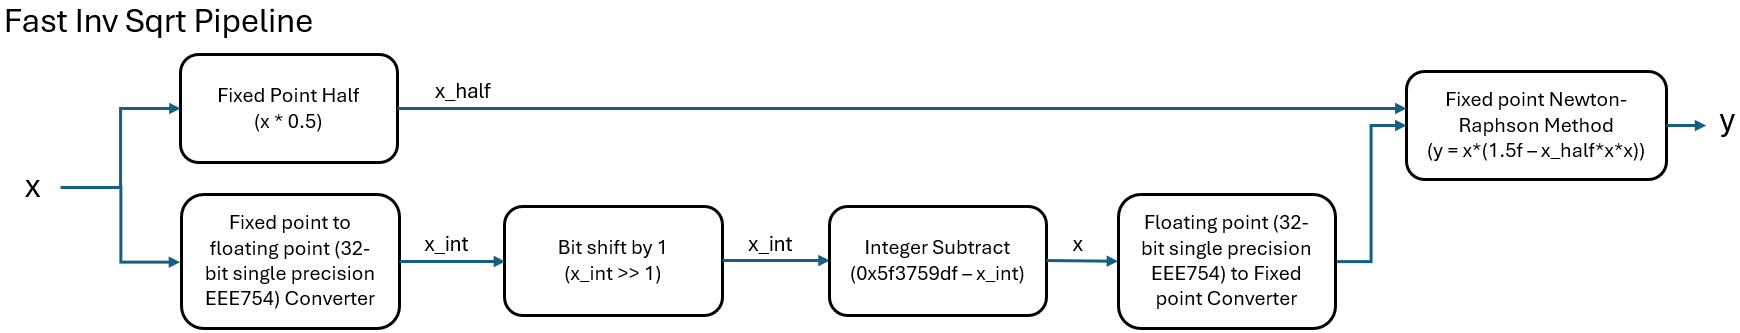

## Constants

SIGNED = 1;

INPUT_WORD_LENGTH = 16;
INPUT_FRACT_LENGTH = 4;

INPUT = 100.952;

## Convert x to a fixed point representation

This replicates the input being passed as in a fixed point format

% fi(v,s,w,f) returns a fixed-point object with value v, signed property value s, word length w, and fraction length f
x = fi(INPUT, ~SIGNED, INPUT_WORD_LENGTH, INPUT_FRACT_LENGTH)

x =   100.9375

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Unsigned
            WordLength: 16
        FractionLength: 4

x.bin

ans = '0000011001001111'

## Compute Half x

x_half = bitsrl(x, 1);
x_half.bin

ans = '0000001100100111'

## Convert to 32 bit floating point EEE754 and Cast as Integer

In HDL the fixed point number will be converted to EEE754 single prescion and then be used in integer operations. (NO FLOATING POINT ARITHMETIC OPERATIONS REQUIRED!)

Convert fixed point to single precision floating point

x_float = single(int(x)) * 2^-x.FractionLength

x_float = single
100.9375

dec2bin(x_float)

ans = '1100100'

Cast as Integer

x_int = typecast(single(x_float), 'uint32')

x_int = uint32
1120526336

dec2bin(x_int, 32)

ans = '01000010110010011110000000000000'

## Perform Bit Shift Right by 1

x_int = bitsrl(x_int, 1)

x_int = uint32
560263168

## Subtract x_int From Magic Hex Value

y0 = uint32(hex2dec("5f3759df")) - x_int

y0 = uint32
1037199839

dec2bin(y0, 32)

ans = '00111101110100100110100111011111'

% magic_hex = fi(hex2dec("5f3759df"), ~SIGNED, 32, 0)
% x_int = fi(x_int, ~SIGNED, 32, 0)
% x = magic_hex - x_int

Integer to floating point Conversion (not required in HDL, just pass x to float to fixed converter)

y0 = typecast(uint32(y0), 'single')

y0 = single
0.1027

Floating point to Fixed point Conversion 

y0 = fi(y0, ~SIGNED, INPUT_WORD_LENGTH, INPUT_FRACT_LENGTH)

y0 =     0.1250

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Unsigned
            WordLength: 16
        FractionLength: 4

y0.bin

ans = '0000000000000010'

## Newton-Raphson Method

`y = x * (1.5f - xhalf * x * x)`

A = x_half * y0 * y0

A =     0.7881

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Unsigned
            WordLength: 48
        FractionLength: 12

% A = fi(single(int(A)) * 2^-A.FractionLength, 0, INPUT_WORD_LENGTH, INPUT_FRACT_LENGTH)
A.bin

ans = '000000000000000000000000000000000000110010011100'

one_and_half = fi(1.5, ~SIGNED, A.WordLength, A.FractionLength)

one_and_half =     1.5000

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Unsigned
            WordLength: 48
        FractionLength: 12

one_and_half.bin

ans = '000000000000000000000000000000000001100000000000'

B = one_and_half - A

B =     0.7119

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Unsigned
            WordLength: 49
        FractionLength: 12

B.bin

ans = '0000000000000000000000000000000000000101101100100'

y_temp = y0 * (one_and_half - A)

y_temp =     0.0890

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Unsigned
            WordLength: 65
        FractionLength: 16

y_temp.bin

ans = '00000000000000000000000000000000000000000000000000001011011001000'

## Normalise word length

y = fi(y_temp, 0, INPUT_WORD_LENGTH, INPUT_FRACT_LENGTH)

y =     0.0625

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Unsigned
            WordLength: 16
        FractionLength: 4

y.bin

ans = '0000000000000001'

## True Inverse Square Root

1/sqrt(INPUT)

ans = 0.0995

## Error

error = abs((single(int(y))*2^-y.FractionLength) - 1/sqrt(INPUT))

error = single
0.0370

## Acceleration Vector Normalisation

x = a_x * a_x + a_y  * a_y + a_z * a_z

max value = 3 * (8 * 9.81)^2 = 2039

16^2 - 1 = 4095

INPUT_WORD_LENGTH = 16;
INPUT_FRACT_LENGTH = 4;

data = readtable("C:\Dev\madgwick_rvfpga\processing\Data\mpu6050_data\MPU6050_ESP32_10000_points.csv");
x = data.ax.^2 + data.ay.^2 + data.az.^2;

### Probability Distribution 

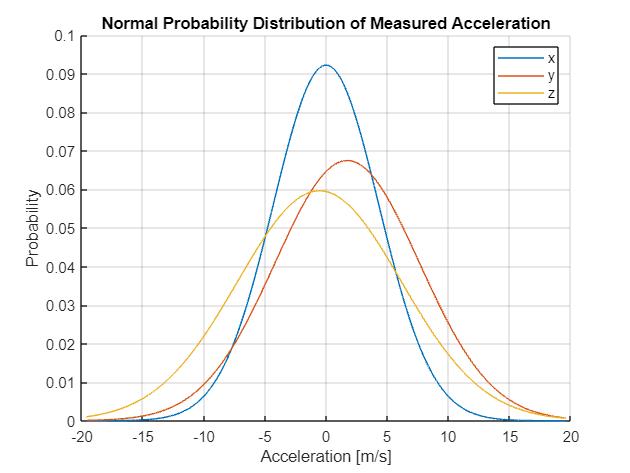

x_pd = -2*9.81:1e-3:2*9.81;
y_ax = pdf(fitdist(data.ax, "Normal"), x_pd);
y_ay = pdf(fitdist(data.ay, "Normal"), x_pd);
y_az = pdf(fitdist(data.az, "Normal"), x_pd);
figure()
hold on
plot(x_pd, y_ax, DisplayName="x")
plot(x_pd, y_ay, DisplayName="y")
plot(x_pd, y_az, DisplayName="z")
legend()
xlabel("Acceleration [m/s]")
ylabel("Probability")
title("Normal Probability Distribution of Measured Acceleration")
grid on

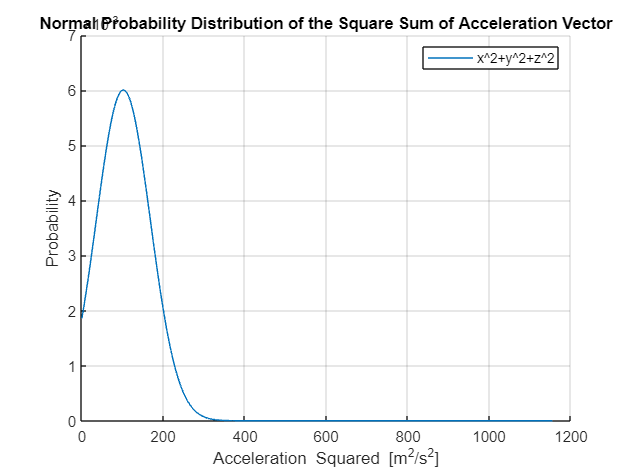

x_pd = 0:0.01:3*(2*9.81)^2;
y = pdf(fitdist(x, "Normal"), x_pd);
figure()
hold on
plot(x_pd, y, DisplayName="x^2+y^2+z^2")
legend(Interpreter="none")
xlabel("Acceleration Squared [{m^2}/{s^2}]")
ylabel("Probability")
title("Normal Probability Distribution of the Square Sum of Acceleration Vector")
grid on

### Run Algorithm

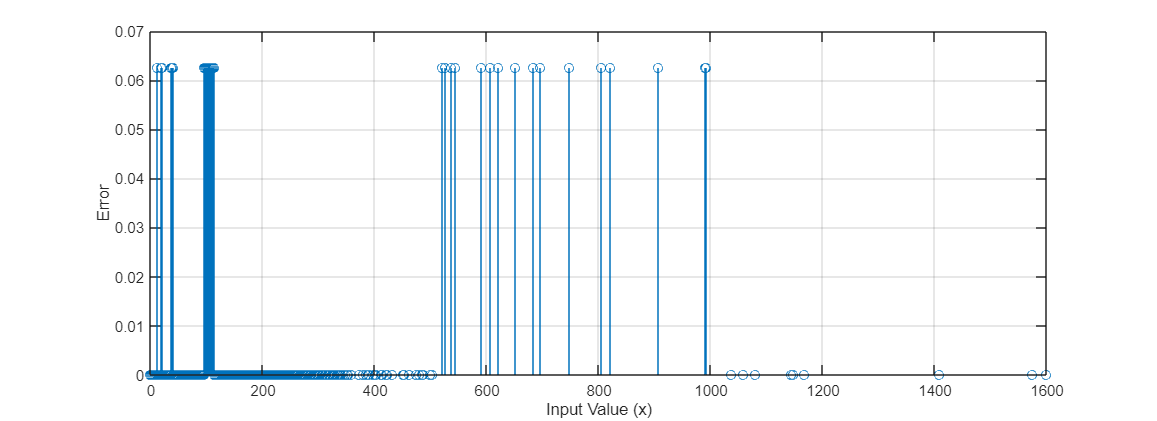

output = zeros(length(x), 3);
for i = 1:length(x)
    [val, fix, err] = fixFastInvSqrt(x(i), INPUT_WORD_LENGTH, INPUT_FRACT_LENGTH);
    output(i, :) = [val; fix; err];
end

fig = figure(Position=[400 400 1100 400]);
stem(x, output(:, 3))
xlabel("Input Value (x)")
ylabel("Error")
grid on

## Attitude Quaternion Normalisation

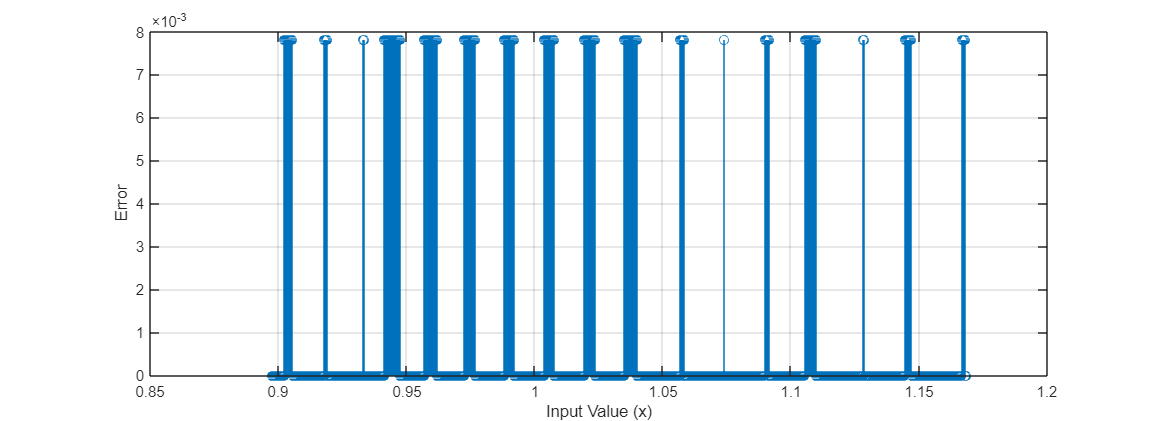

INPUT_WORD_LENGTH = 8;
INPUT_FRACT_LENGTH = 7;

data = readtable("C:\Dev\madgwick_rvfpga\processing\Data\filtered_data\filtered_output_23-06-24_16-47-37.csv");
x = data.q_w.^2 + data.q_x.^2 + data.q_y.^2 + data.q_z.^2;
output = zeros(length(x), 3);
for i = 1:length(x)
    [val, fix, err] = fixFastInvSqrt(x(i), INPUT_WORD_LENGTH, INPUT_FRACT_LENGTH);
    output(i, :) = [val; fix; err];
end

fig = figure(Position=[400 400 1100 400]);
stem(x, output(:, 3))
xlabel("Input Value (x)")
ylabel("Error")
grid on

## fixFastInvSqrt Function

function [val, fix, err] = fixFastInvSqrt(input, word_length, fract_length)

    x = fi(input, 0, word_length, fract_length);

    % Compute x_half
    half = fi(0.5, 0, 1, 1);
    x_half = x * half;

    % Convert to float
    x_float = single(int(x)) * 2^-x.FractionLength;
    x_int = typecast(single(x_float), 'uint32'); % Cast as integer

    % Bit shift right by 1
    x_int = bitsrl(x_int, 1);

    % Integer subtract from magic hex value
    x = uint32(hex2dec("5f3759df")) - x_int;

    % Convert back to fixed point
    x = typecast(uint32(x), 'single'); % Cast as float
    x = fi(x, 0, word_length, fract_length);

    % Newton-Raphson method
    A = x_half * x * x;
    one_and_half = fi(1.5, 0, A.WordLength, A.FractionLength);
    fix = x * (one_and_half - A);

    % Normalise word length
    fix = fi(fix, 0, word_length, fract_length);

    % Convert to decimal
    val = single(int(fix)) * 2^-fix.FractionLength;

    % Compute error
    err = abs(val - 1/sqrt(input));

end